clear
clc

syms sweep Cl_design Mdd Cl_cruise t_c


sweep_historical = 22;
design_cl = 0.33759

design_cl = 0.3376


% t_c = 0.12;
ka = 0.87;
Mcruise = 0.75;

Mdd = Mcruise*sqrt(cosd(sweep))

$$Mdd = \frac{3\,\sqrt{\cos\left(\frac{\pi \,\mathrm{sweep}}{180}\right)}}{4}$$


Cl_airfoil = 10*(ka - t_c - Mdd)

$$Cl\_airfoil = \frac{87}{10}-\frac{15\,\sqrt{\cos\left(\frac{\pi \,\mathrm{sweep}}{180}\right)}}{2}-10\,t_{c}$$


Cl_cruise(sweep,t_c) = Cl_airfoil*(0.9*0.95*cosd(sweep))

$$Cl\_cruise(sweep, t\_c) = -\frac{171\,\cos\left(\frac{\pi \,\mathrm{sweep}}{180}\right)\,\left(10\,t_{c}+\frac{15\,\sqrt{\cos\left(\frac{\pi \,\mathrm{sweep}}{180}\right)}}{2}-\frac{87}{10}\right)}{200}$$


simplify(Cl_cruise)

$$ans(sweep, t\_c) = -\frac{171\,\cos\left(\frac{\pi \,\mathrm{sweep}}{180}\right)\,\left(10\,t_{c}+\frac{15\,\sqrt{\cos\left(\frac{\pi \,\mathrm{sweep}}{180}\right)}}{2}-\frac{87}{10}\right)}{200}$$

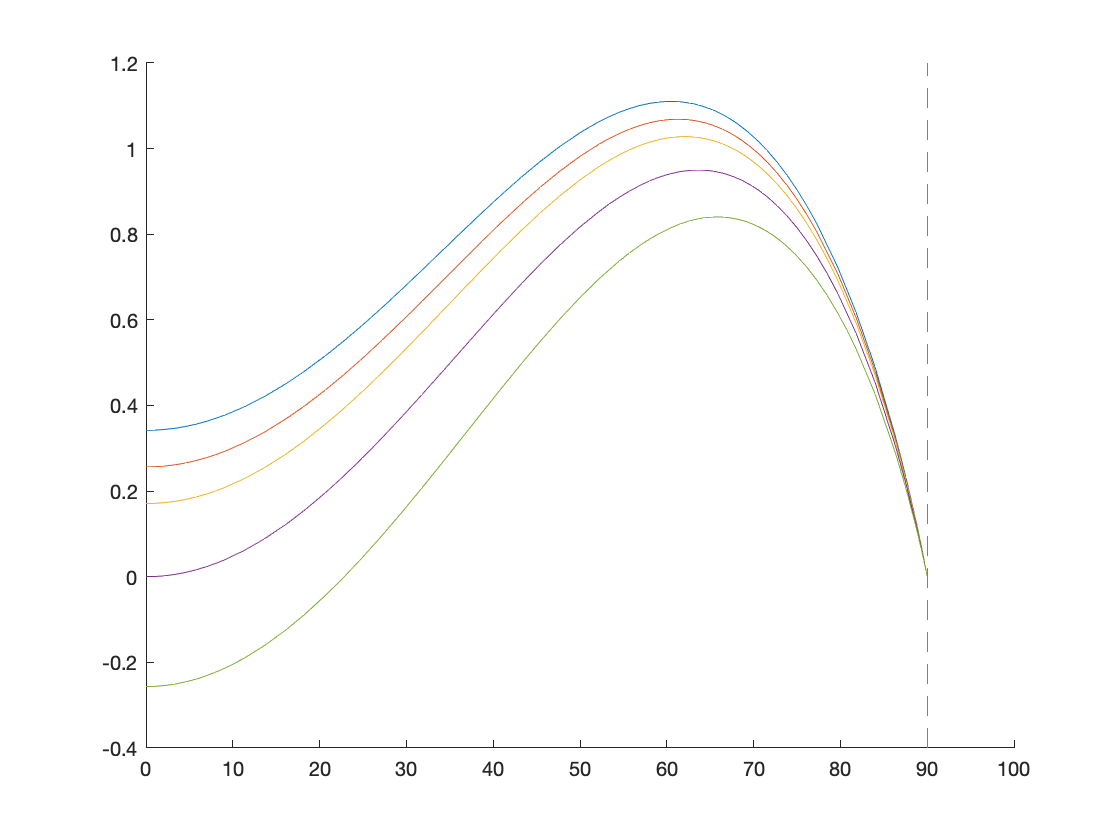


figure
hold on
fplot(@(x) Cl_cruise(x,0.08),[0,100])
fplot(@(x) Cl_cruise(x,0.09),[0,100])
fplot(@(x) Cl_cruise(x,0.10),[0,100])
fplot(@(x) Cl_cruise(x,0.12),[0,100])
fplot(@(x) Cl_cruise(x,0.15),[0,100])


% fcn = subs(Cl_cruise,t_c,0.12);
options = optimset('Display','off')

options = struct with fields:
                   Display: 'off'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
      

required_sweep_08 = fsolve(@(x) double(Cl_cruise(x,0.08)) - design_cl, 20,options)

required_sweep_08 = -0.1197

required_sweep_09 = fsolve(@(x) double(Cl_cruise(x,0.09)) - design_cl, 20,options)

required_sweep_09 = 13.6258

required_sweep_10 = fsolve(@(x) double(Cl_cruise(x,0.10)) - design_cl, 20,options)

required_sweep_10 = 19.5300

required_sweep_12 = fsolve(@(x) double(Cl_cruise(x,0.12)) - design_cl, 20,options)

required_sweep_12 = 27.8101

required_sweep_15 = fsolve(@(x) double(Cl_cruise(x,0.15)) - design_cl, 20,options)

required_sweep_15 = 36.9168


Mdd_08 = double(subs(Mdd,sweep,required_sweep_08))

Mdd_08 = 0.7500

Mdd_09 = double(subs(Mdd,sweep,required_sweep_09))

Mdd_09 = 0.7394

Mdd_10 = double(subs(Mdd,sweep,required_sweep_10))

Mdd_10 = 0.7281

Mdd_12 = double(subs(Mdd,sweep,required_sweep_12))

Mdd_12 = 0.7054

Mdd_15 = double(subs(Mdd,sweep,required_sweep_15))

Mdd_15 = 0.6706


Cl_section_design_08 = design_cl/(0.9*0.95*cosd(required_sweep_08))

Cl_section_design_08 = 0.3948

Cl_section_design_09 = design_cl/(0.9*0.95*cosd(required_sweep_09))

Cl_section_design_09 = 0.4063

Cl_section_design_10 = design_cl/(0.9*0.95*cosd(required_sweep_10))

Cl_section_design_10 = 0.4189

Cl_section_design_12 = design_cl/(0.9*0.95*cosd(required_sweep_12))

Cl_section_design_12 = 0.4464

Cl_section_design_15 = design_cl/(0.9*0.95*cosd(required_sweep_15))

Cl_section_design_15 = 0.4939